clear
clc

# Dynamic Goals_Based Wealth Management Using Reinforcement Learning and Dynamic Programming

## Building constant variables

% ------- mu--------

n_actions = 15;% size of action space

mus_l = 0.0526;  % left end of mu vector
mus_r = 0.0886;  % right end of mu vector
mus = mus_l: (mus_r-mus_l)/(n_actions-1): mus_r;




% ------- sigma--------
% prams to get sigs
avg_arr = [0.0493, 0.0770, 0.0886];
cov_mat = [ [0.0017, -0.0017, -0.0021];[-0.0017, 0.0396, 0.03086];[-0.0021, 0.0309, 0.0392] ];



## Action Space

% mu_sig pairs
actions_mu_sig = zeros(n_actions, 2); % action space = [mu1, sigma1;
                                               %mu2, sigma2; ]
[a,b,c] = action_prams_to_get_sigs(avg_arr,cov_mat);
actions_mu_sig(:,1) = mus';
actions_mu_sig(:,2) = action_get_sigs(actions_mu_sig(:,1), a,b,c);

## State Space

w0 = 150;
G = 200;
rho = 1;  % may not be that gamma
T = 10;
cash = zeros(T,1);
state_wealthspace = state_gen_wealthgrid(w0, cash, actions_mu_sig, rho); % find all possible wealth 

## Initialization

%% Transition Probability
            % for                       (i, t, a, j)
[TP, TP_cmf_j] = Init_TP(state_wealthspace, actions_mu_sig, cash, T);


%% Initilize Q table
            % for                       (i, t, a)
Q = Init_Q(state_wealthspace, actions_mu_sig, T);


%% Initilize R table
            % for                       (i, t)
R = Init_R(state_wealthspace, G, T);


%% Initilize V table   
            % for state(money, t)       (i, t)
V = R;

## Train Q-learning Agent (1, with w0=150)

maxItr = 100000;
alpha = 0.2;
gamma = 0.9;
qln_prams = [T, w0, maxItr, alpha, gamma, G];
Q = Qlearning(Q, R, TP_cmf_j, state_wealthspace, qln_prams);

## Decision Making with Qln Agent (1)

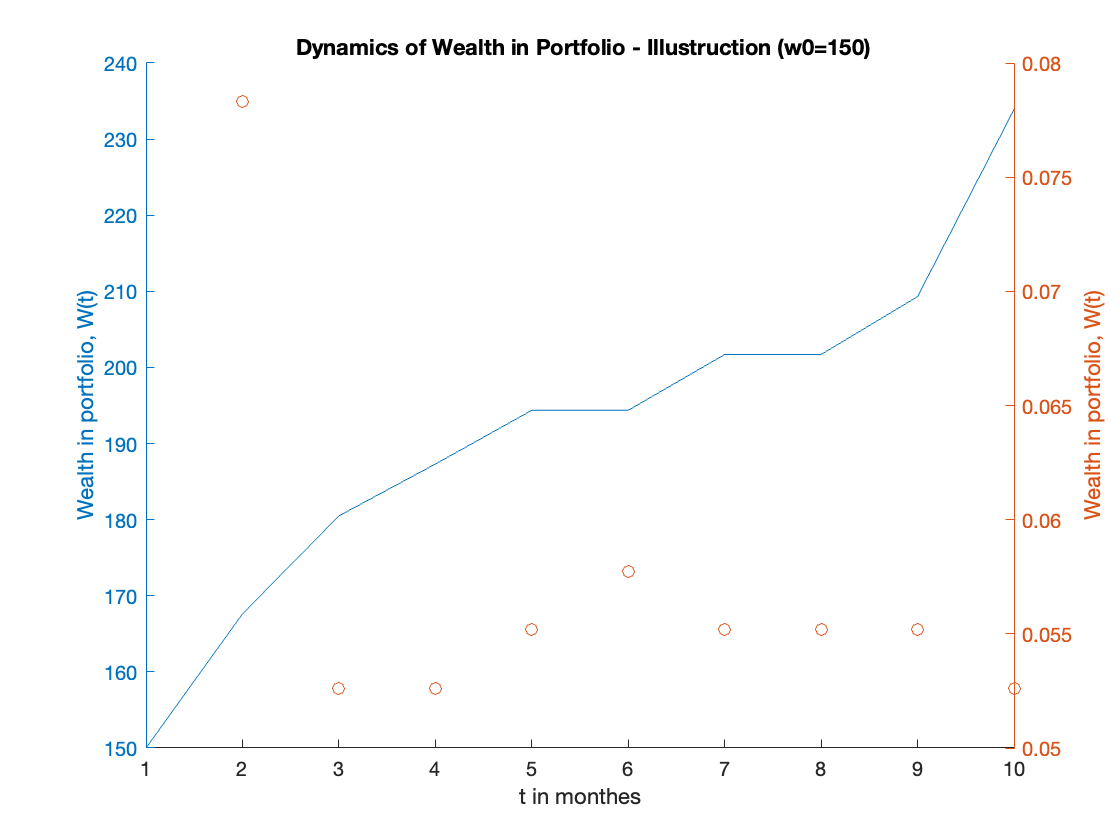

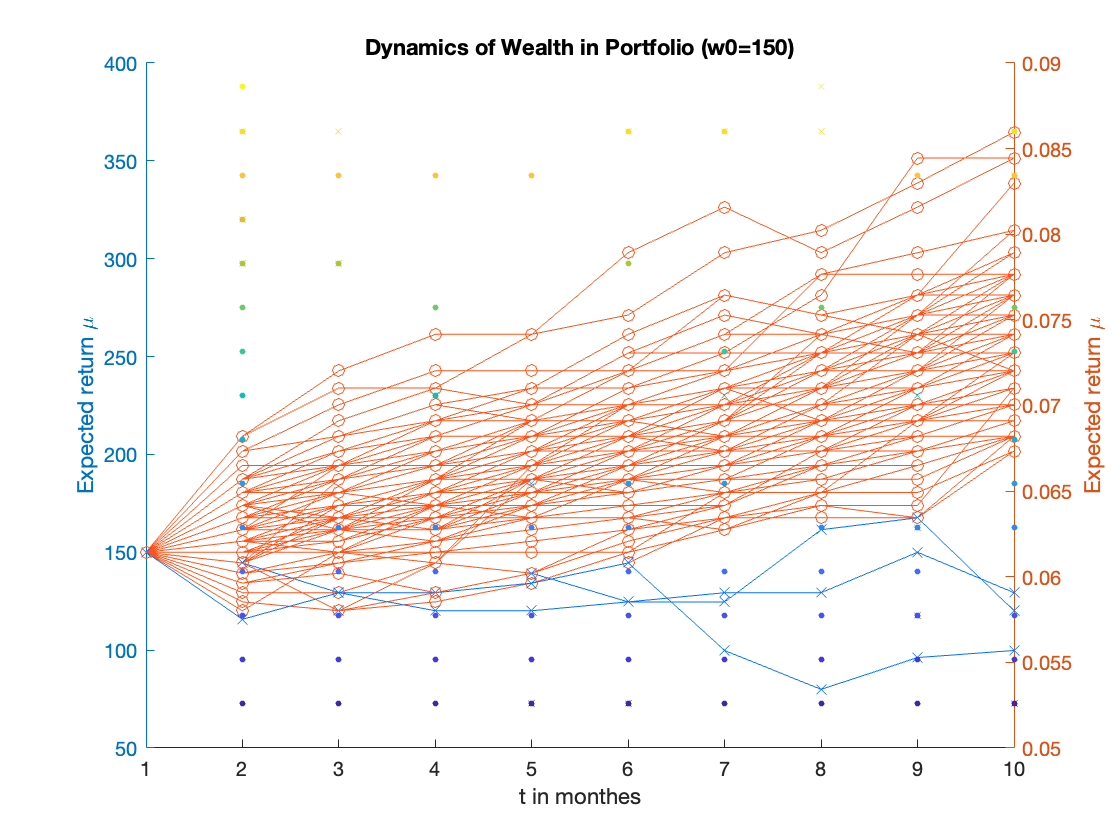

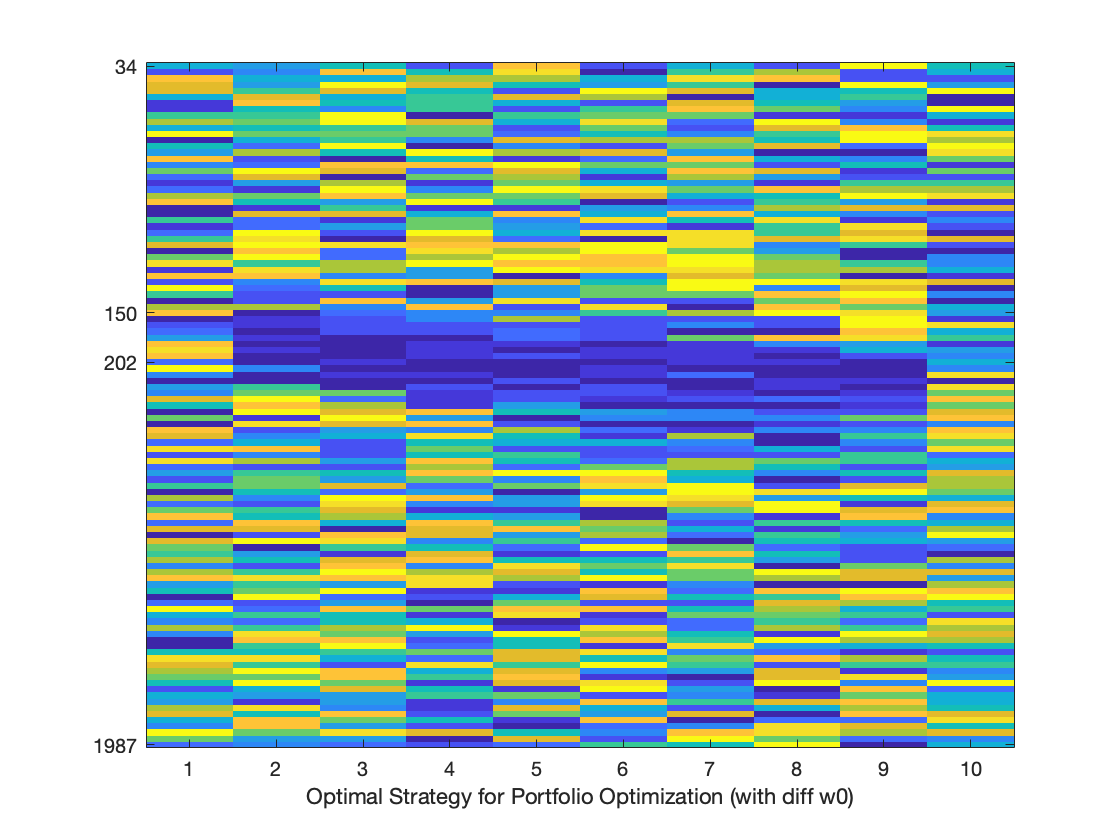

[mus_qln, trace] = Qln_suggestion(Q, R, TP_cmf_j, state_wealthspace, qln_prams);

total_itr = 100;
n = Qln_plot(Q, R, TP_cmf_j, actions_mu_sig, state_wealthspace, qln_prams, total_itr);

## Train Q-learning Agent (2, with w0=diff values)

w0_list = [225, 160, 90, 140, 1000, 120, 500, 100, 275, 80, 175, 75, 1500, 70, 130, 40, 170, 50, 185, 60, 95];
for i = 1:length(w0_list)
    w0 = w0_list(i);
    qln_prams = [T, w0, maxItr, alpha, gamma, G];
    Q = Qlearning(Q, R, TP_cmf_j, state_wealthspace, qln_prams);
end

## Decision Making with Qln Agent (2)

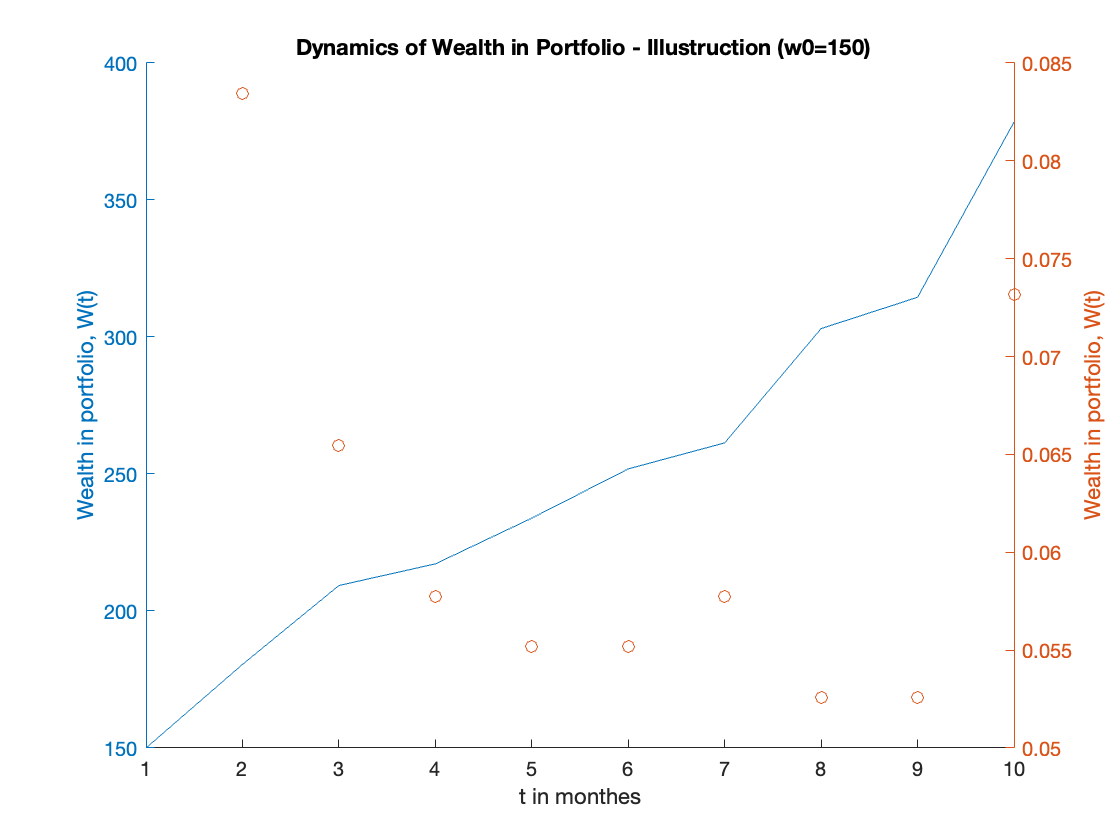

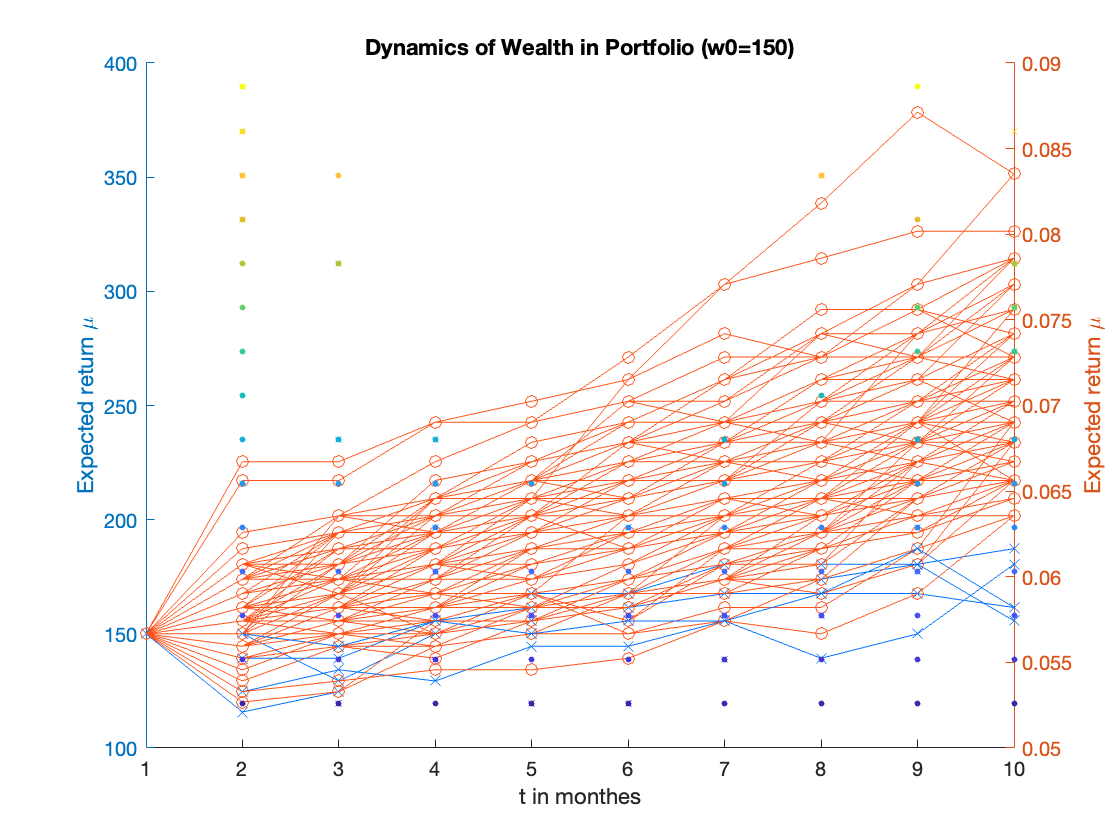

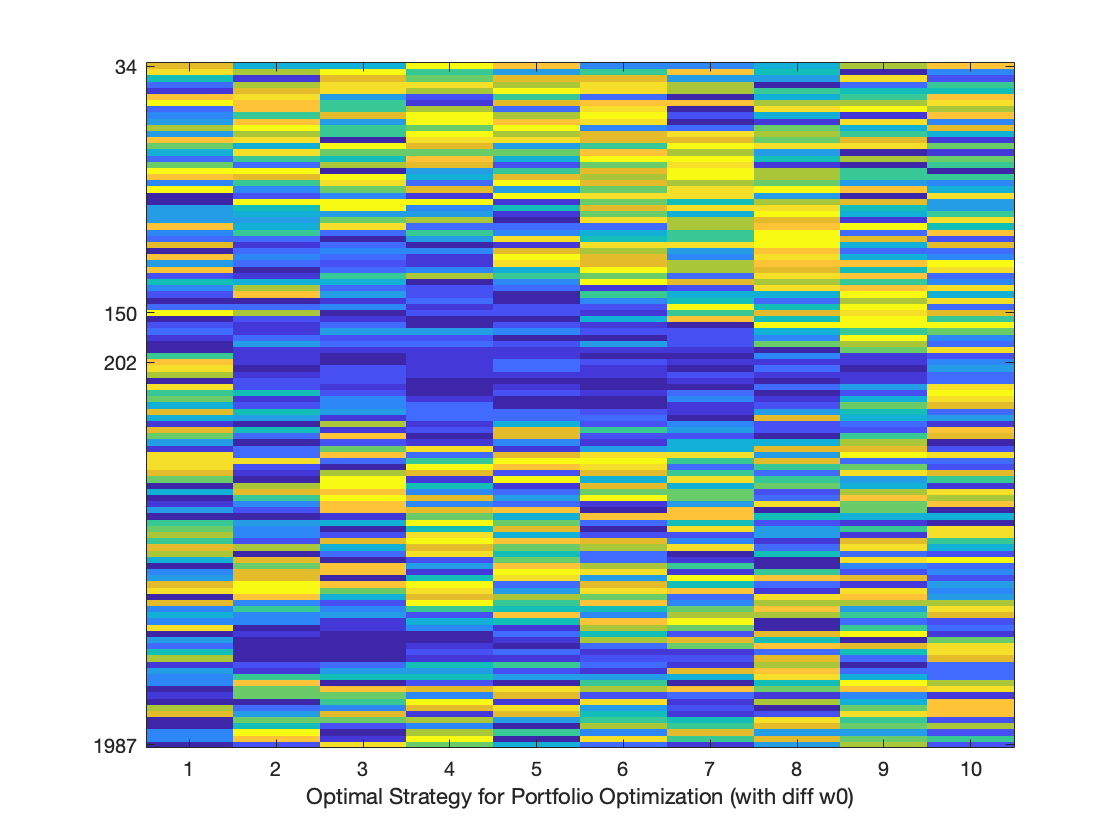

w0 = 150;
qln_prams = [T, w0, maxItr, alpha, gamma, G];
[mus_qln, trace] = Qln_suggestion(Q, R, TP_cmf_j, state_wealthspace, qln_prams);

total_itr = 100;
n = Qln_plot(Q, R, TP_cmf_j, actions_mu_sig, state_wealthspace, qln_prams, total_itr);

## Baseline 

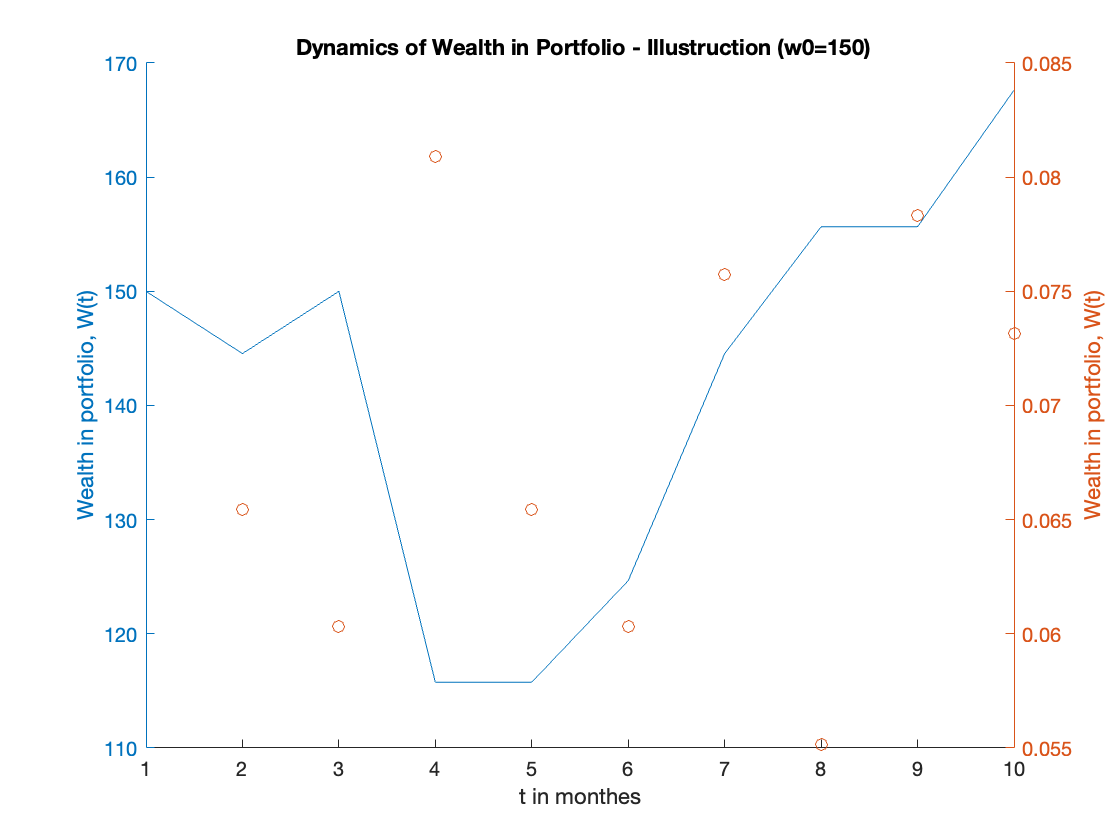

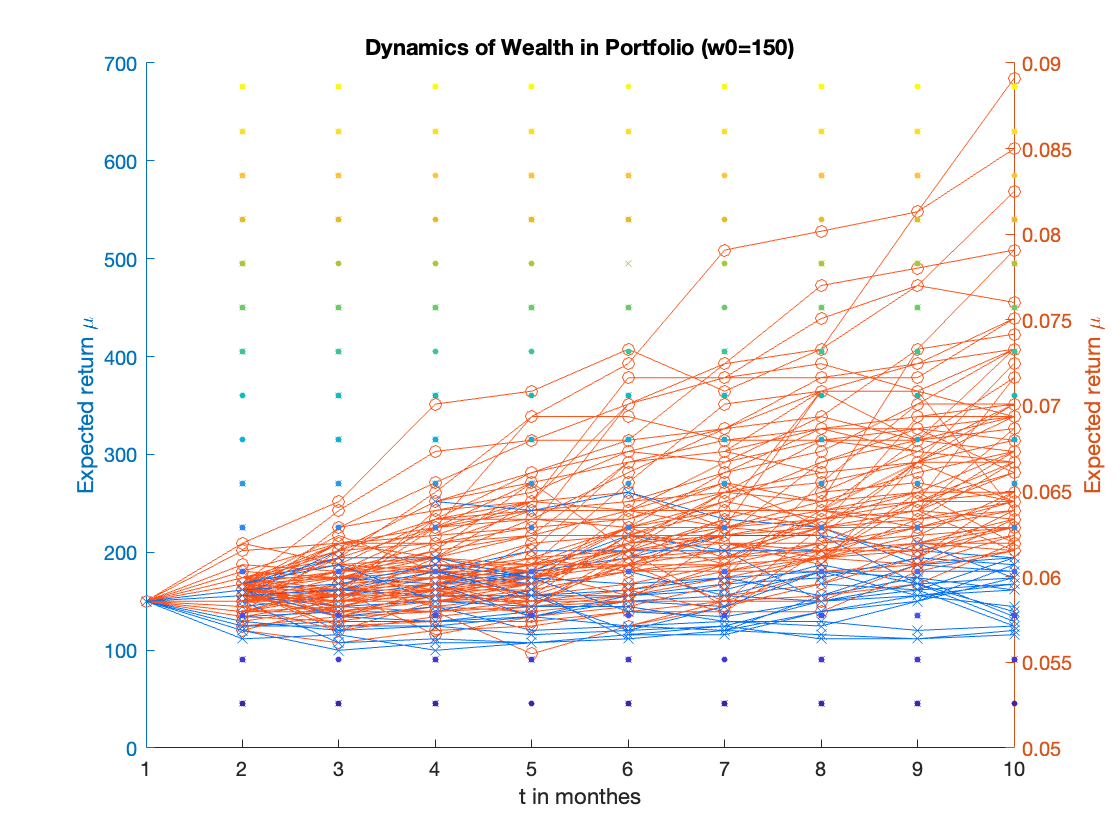

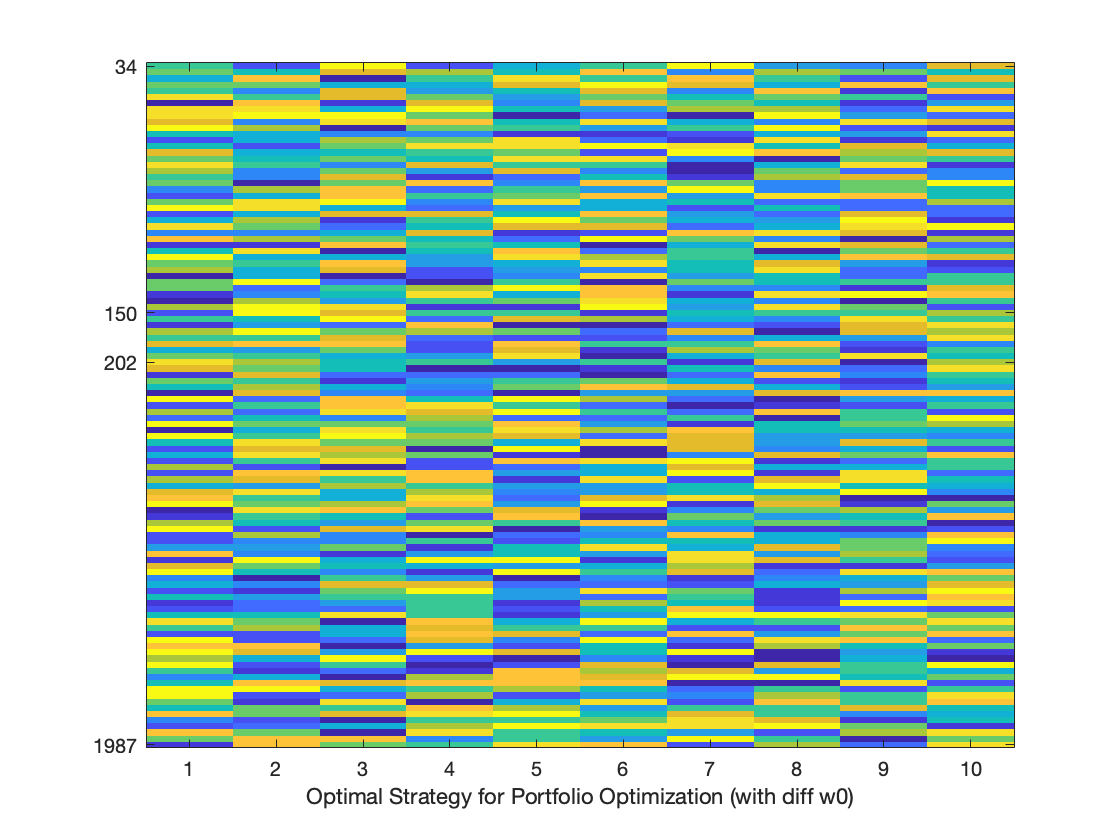

Q = Init_Q(state_wealthspace, actions_mu_sig, T);
[mus_qln, trace] = Qln_suggestion(Q, R, TP_cmf_j, state_wealthspace, qln_prams);

total_itr = 100;
n = Qln_plot(Q, R, TP_cmf_j, actions_mu_sig, state_wealthspace, qln_prams, total_itr);

clear
clc

# Dynamic Goals_Based Wealth Management Using Dynamic Programming

## Initialization

%% Action Space

% ------- mu--------

% parms to define action space
n_actions = 15;% size of action space

mus_l = 0.0526;  % left end of mu vector
mus_r = 0.0886;  % right end of mu vector
mus = mus_l: (mus_r-mus_l)/(n_actions-1): mus_r;



% ------- sigma--------
% prams to get sigs
avg_arr = [0.0493, 0.0770, 0.0886];
cov_mat = [ [0.0017, -0.0017, -0.0021];[-0.0017, 0.0396, 0.03086];[-0.0021, 0.0309, 0.0392] ];



% mu_sig pairs
actions_mu_sig = zeros(n_actions, 2); % action space = [mu1, sigma1;
                                               %mu2, sigma2; ]
[a,b,c] = action_prams_to_get_sigs(avg_arr,cov_mat);
actions_mu_sig(:,1) = mus';
actions_mu_sig(:,2) = action_get_sigs(actions_mu_sig(:,1), a,b,c);
                                               


%% State Space


w0 = 150;
G = 200;
rho = 1;  % may not be that gamma
T = 10;
cash = zeros(T,1);
state_wealthspace = state_gen_wealthgrid(w0, cash, actions_mu_sig, rho); % find all possible wealth 




%% Transition Probability
            % for                       (i, t, a, j)
[TP, TP_cmf_j] = Init_TP(state_wealthspace, actions_mu_sig, cash, T);

 
%% Initilize V table   
            % for state(money, t)       (i, t)
V = Init_V(state_wealthspace, G, T);

## Dynamic Programming Iterations

a_2 =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [840 738 560 420]
       Units: 'pixels'

  Show all properties


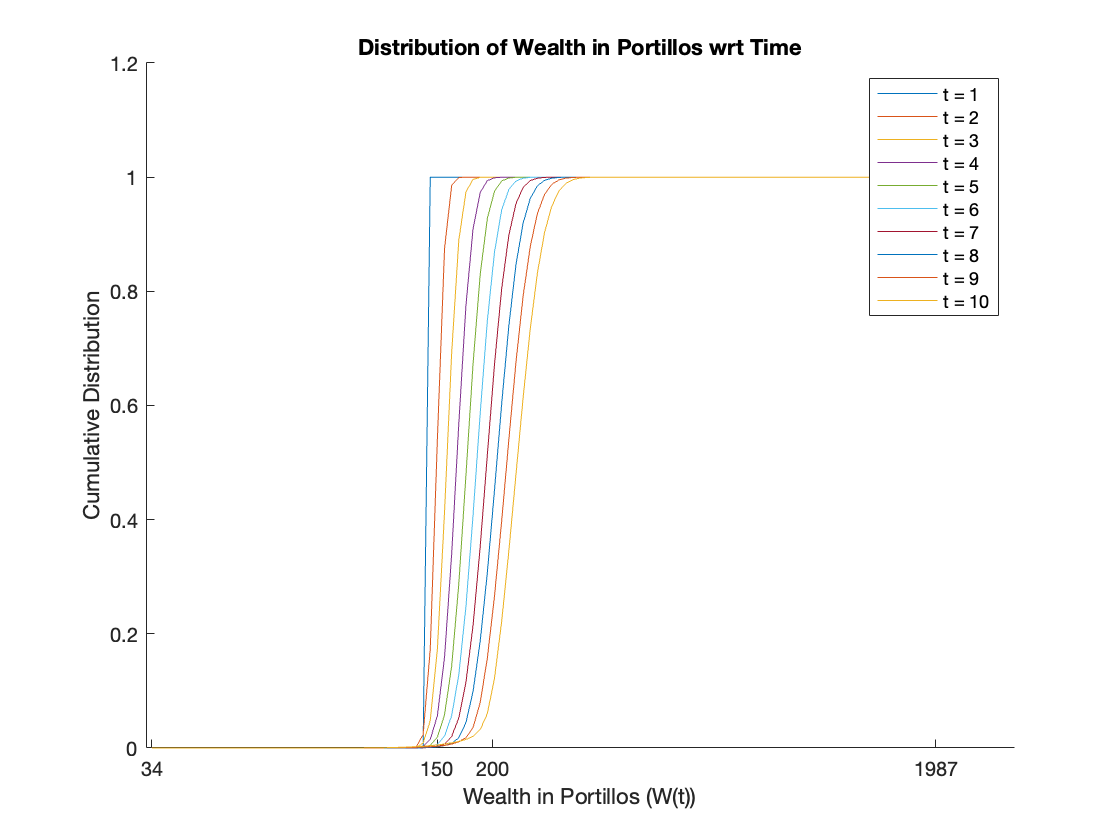

b_1 =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [840 738 560 420]
       Units: 'pixels'

  Show all properties


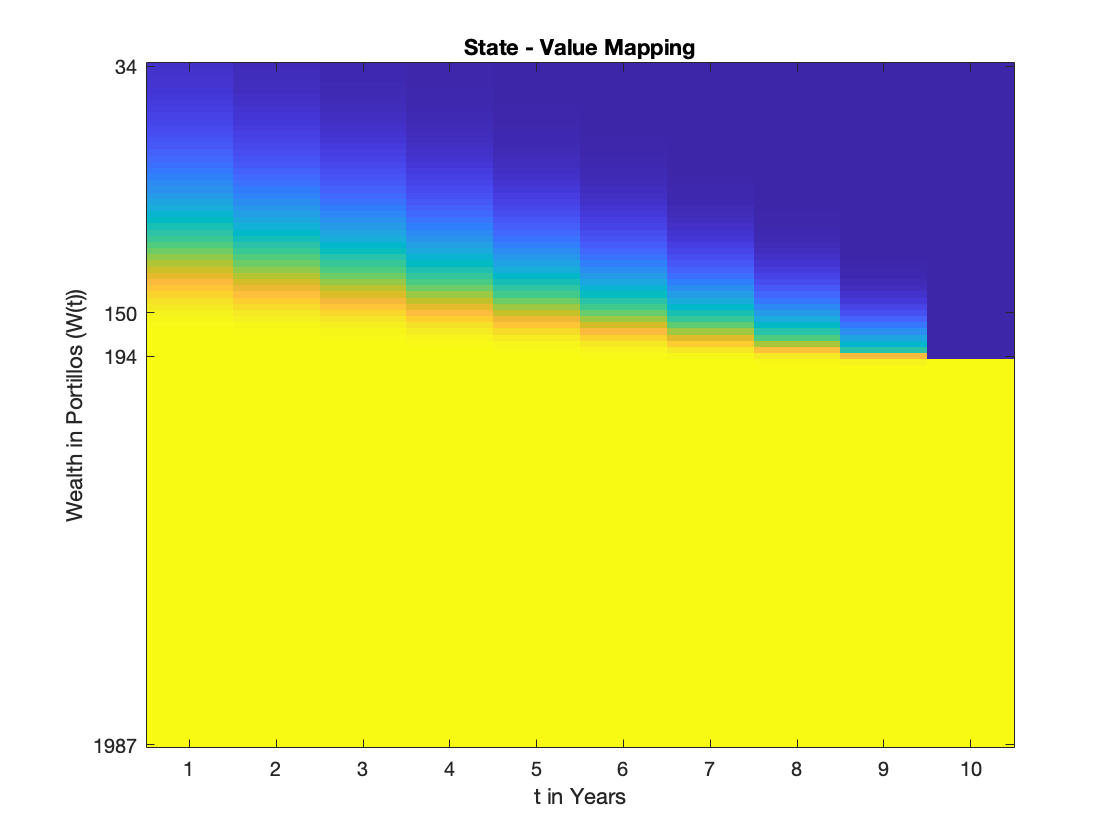

%% train Q learning agent -- w0 = 150
maxItr = 10;
alpha = 0.2;
gamma = 0.9;
dp_prams = [T, w0, maxItr, alpha, gamma, G];
[V, p_table] = DynamicProgramming(V, TP, state_wealthspace, dp_prams);


%% DP suggestion   -- w0 = 150
a_2 = DP_plot(V, p_table, state_wealthspace, T, w0, G);

*Author: Botao Zhang (bz2462@columbia.edu) *